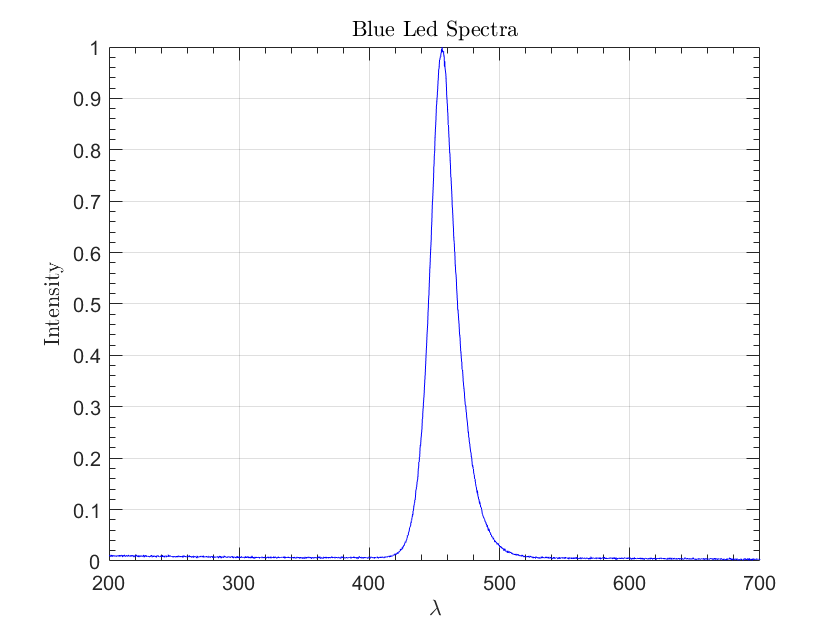

% ================= Blue LED ================= %
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\BLED.txt");
lambda = d(:,1);
Ia = d(:,2);
Ia = normalize_intensity(Ia);
plot(lambda,Ia, "Color", [0 0 1])
title('Blue Led Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([200 700])

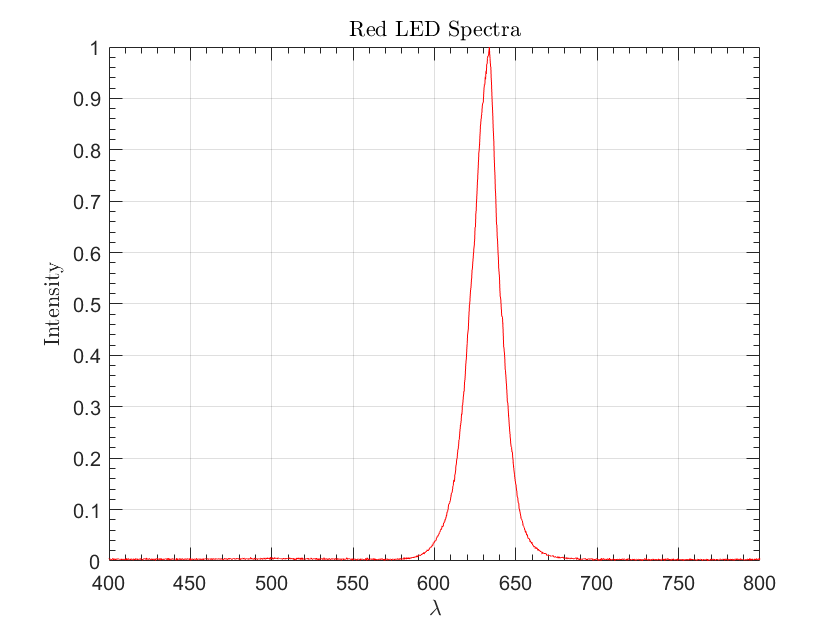


% ================= Red LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLED.txt");
Ib = d(:,2);
Ib = normalize_intensity(Ib);
plot(lambda,Ib, "Color", [1 0 0])
title('Red LED Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([400 800])

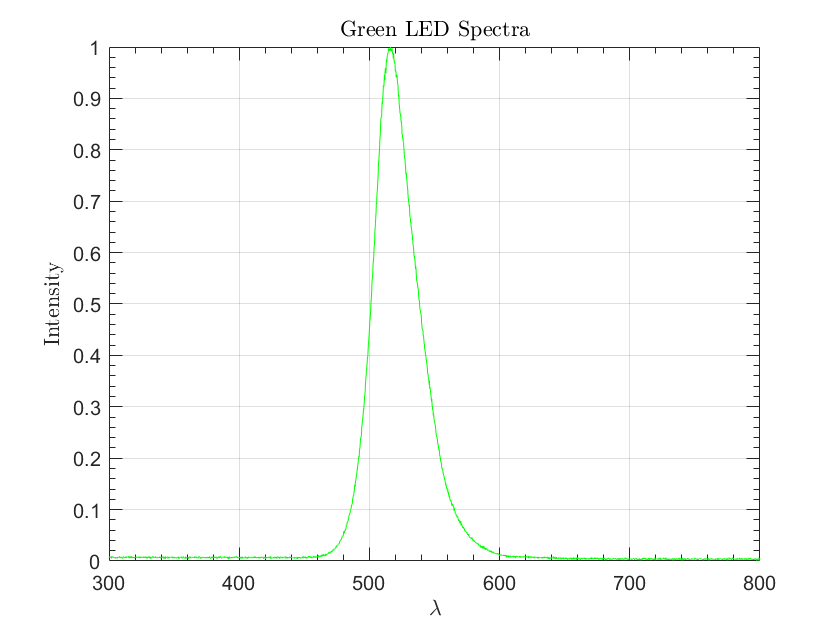


% ================= Green LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\GLED.txt");
Ic = d(:,2);
Ic = normalize_intensity(Ic);
plot(lambda,Ic, "Color", [0 1 0])
title('Green LED Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([300 800])

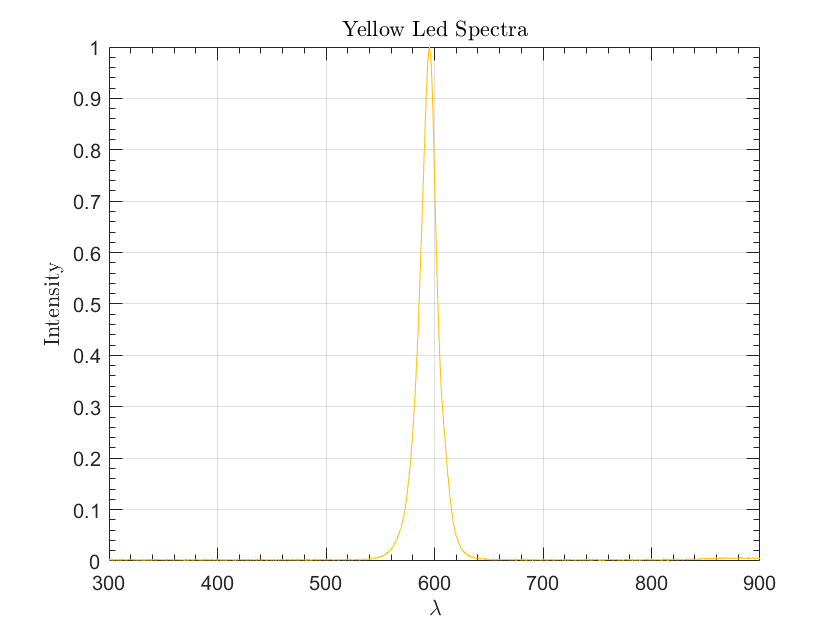


% ================= Yellow LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\YLED.txt");
Id = d(:,2);
Id = normalize_intensity(Id);
plot(lambda,Id, "Color", "#FFBF00")
title('Yellow Led Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([300 900])

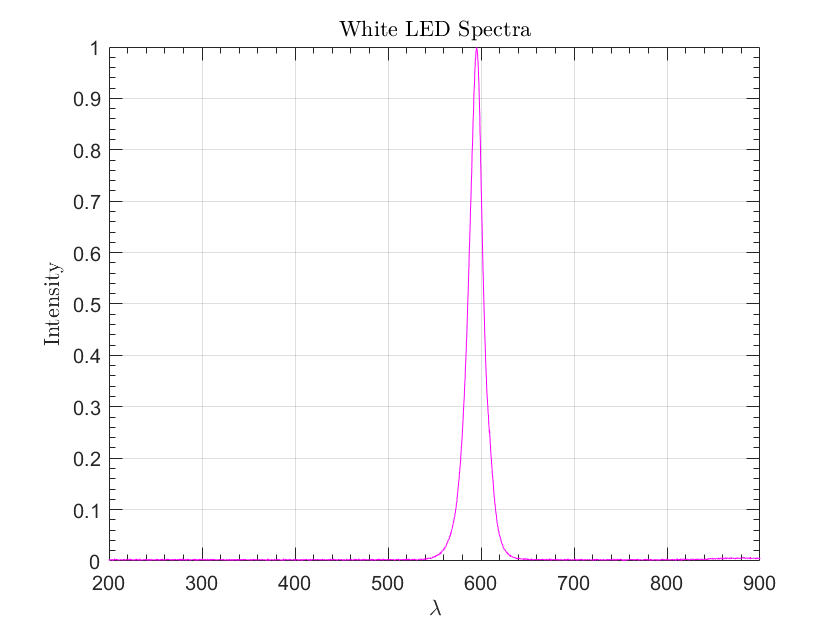


% ================= White LED ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\WLED.txt");
Ie = d(:,2);
Ie = normalize_intensity(Ie);
plot(lambda,Id, "Color", [1 0 1])
title('White LED Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([200 900])

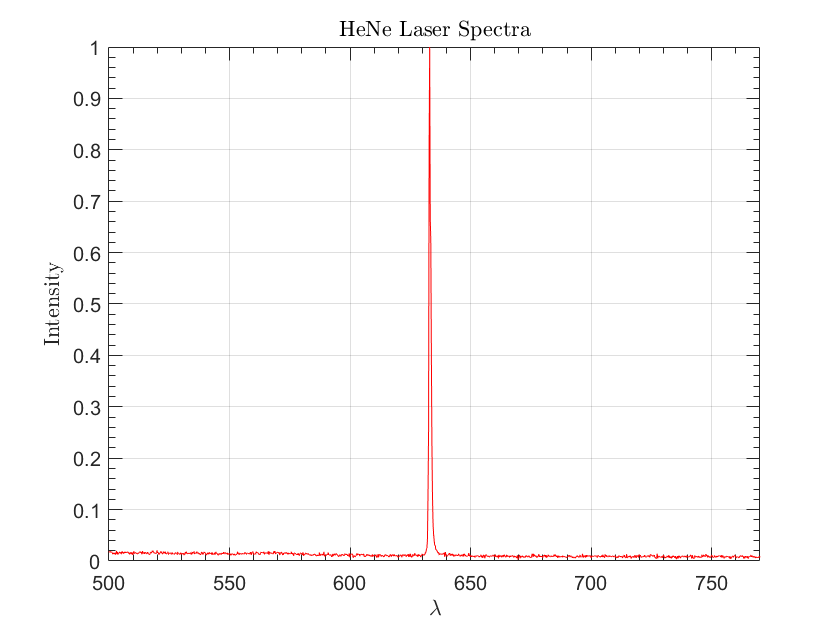


% ================= HeNE Laser ================= %

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLASER.txt");
If = d(:,2);
If = normalize_intensity(If);
plot(lambda,If, "Color", [1 0 0])
title('HeNe Laser Spectra', "Interpreter", "latex"); 
xlabel('$\lambda$', "Interpreter", "latex"); 
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
xlim([500 770])

function norm_I = normalize_intensity(I)

    norm_I = (I - min(I))./(max(I)-min(I));

end